### **loading the homecage condition files**

pre_home = load("presleep_homecage.mat");
post_home = load("postsleep_homecage.mat");

### loading the encoding condition files

pre_enc = load("presleep_encoding.mat");
post_enc = load("postsleep_encoding.mat");

### loading the retrieval condition files

pre_ret = load("presleep_retrieval.mat");
post_ret = load("postsleep_retrieval.mat");

### Plotting

rats = {'Rat1','Rat2','Rat4','Rat7','Rat8'};
r0 = [];r1 = []; r2 = [];r3 = []; r4 = [];s0 = []; s1 = []; s2 = [];s3 = []; s4 = [];
d0 = [];d1 = []; d2 = [];d3 = []; d4 = [];
for k=1:numel(rats')
    r0 = [r0, length(pre_home.pre_cond1.ripples.hour1.(rats{k}))];
    r1 = [r1, length(post_home.post_cond1.ripples.hour1.(rats{k}))];
    r2 = [r2, length(post_home.post_cond1.ripples.hour2.(rats{k}))];
    r3 = [r3, length(post_home.post_cond1.ripples.hour3.(rats{k}))];
    r4 = [r4, length(post_home.post_cond1.ripples.hour4.(rats{k}))];
    s0 = [s0, length(pre_home.pre_cond1.spindles.hour1.(rats{k}))];
    s1 = [s1, length(post_home.post_cond1.spindles.hour1.(rats{k}))];
    s2 = [s2, length(post_home.post_cond1.spindles.hour2.(rats{k}))];
    s3 = [s3, length(post_home.post_cond1.spindles.hour3.(rats{k}))];
    s4 = [s4, length(post_home.post_cond1.spindles.hour4.(rats{k}))];
    d0 = [d0, length(pre_home.pre_cond1.deltas.hour1.(rats{k}))];
    d1 = [d1, length(post_home.post_cond1.deltas.hour1.(rats{k}))];
    d2 = [d2, length(post_home.post_cond1.deltas.hour2.(rats{k}))];
    d3 = [d3, length(post_home.post_cond1.deltas.hour3.(rats{k}))];
    d4 = [d4, length(post_home.post_cond1.deltas.hour4.(rats{k}))];
end

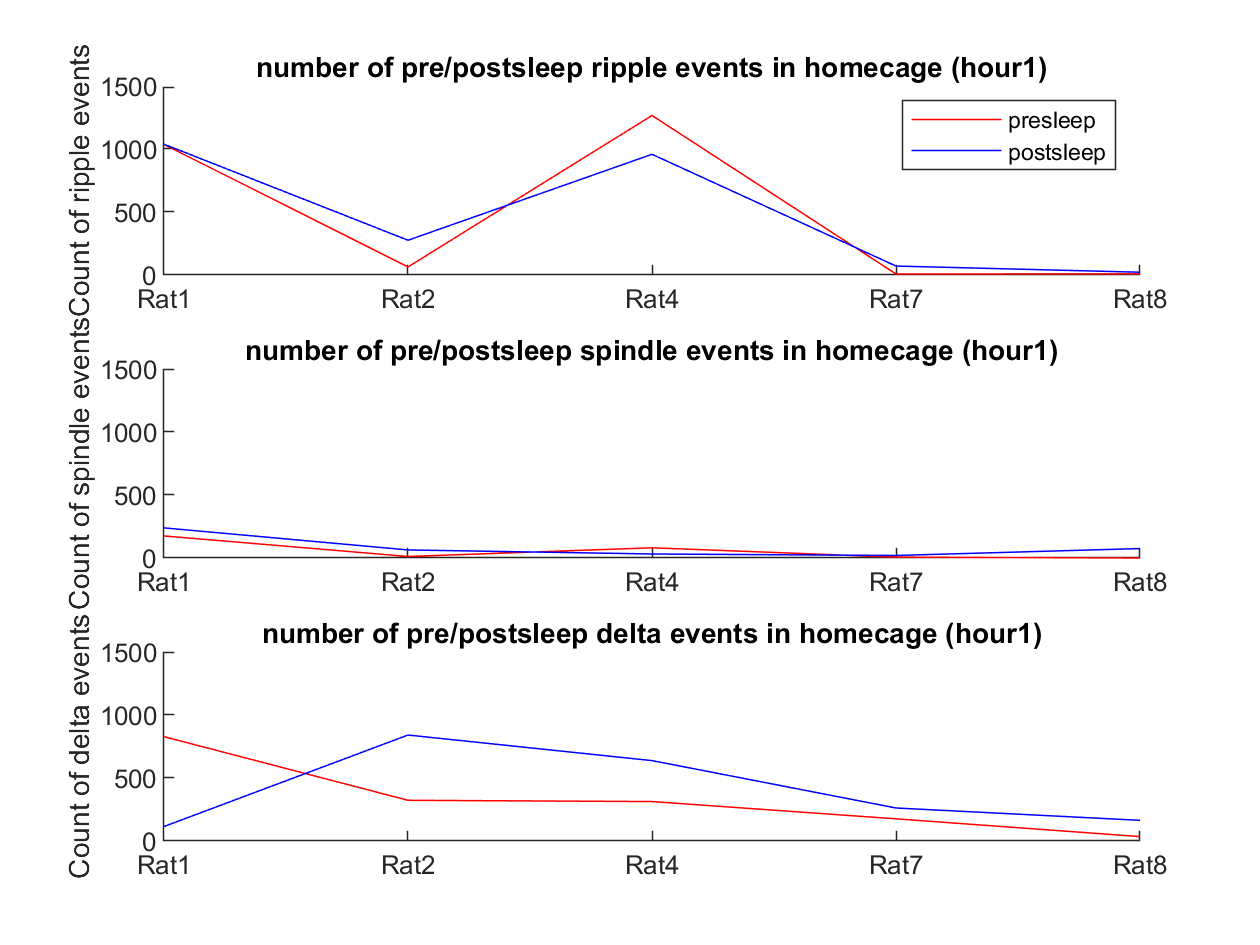

subplot(3,1,1);
hold on
plot(r0 , 'r-');
plot(r1 , 'b-');
hold off
title('number of pre/postsleep ripple events in homecage (hour1)');
xlim([1 5]);
ylim([0 1500]);
ylabel("Count of ripple events")
xticks([1 2 3 4 5]);
xticklabels({'Rat1','Rat2','Rat4', 'Rat7', 'Rat8'});
legend(["presleep","postsleep"]);

subplot(3,1,2);
hold on
plot(s0 , 'r-');
plot(s1 , 'b-');
hold off
title('number of pre/postsleep spindle events in homecage (hour1)');
xlim([1 5]);
ylim([0 1500]);
ylabel("Count of spindle events")
xticks([1 2 3 4 5]);
xticklabels({'Rat1','Rat2','Rat4', 'Rat7', 'Rat8'});

subplot(3,1,3);
hold on
plot(d1 , 'r-');
plot(d2 , 'b-');
hold off
title('number of pre/postsleep delta events in homecage (hour1)');
xlim([1 5]);
ylim([0 1500]);
ylabel("Count of delta events")
xticks([1 2 3 4 5]);
xticklabels({'Rat1','Rat2','Rat4', 'Rat7', 'Rat8'});

**Plotting2**

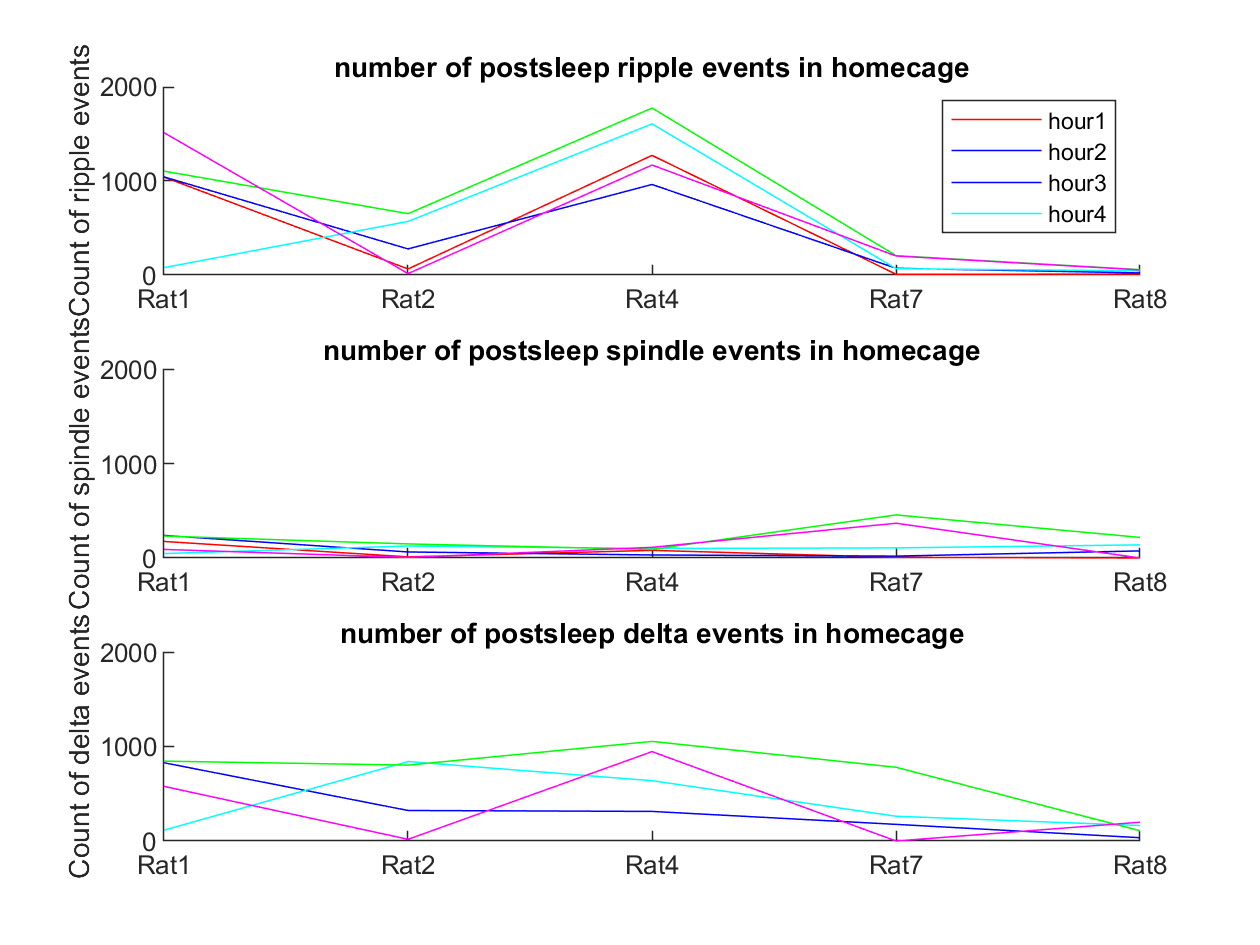

subplot(3,1,1);
hold on
plot(r1 ,"b");
plot(r2 ,"c");
plot(r3 , "g");
plot(r4 , "m");
hold off
title('number of postsleep ripple events in homecage');
xlim([1 5]);
ylim([0 2000]);
ylabel("Count of ripple events")
xticks([1 2 3 4 5]);
xticklabels({'Rat1','Rat2','Rat4', 'Rat7', 'Rat8'});
legend(["hour1","hour2","hour3","hour4"]);

subplot(3,1,2);
hold on
plot(s1 ,"b");
plot(s2 ,"c");
plot(s3 , "g");
plot(s4 , "m");
hold off
title('number of postsleep spindle events in homecage');
xlim([1 5]);
ylim([0 2000]);
ylabel("Count of spindle events")
xticks([1 2 3 4 5]);
xticklabels({'Rat1','Rat2','Rat4', 'Rat7', 'Rat8'});

subplot(3,1,3);
hold on
plot(d1 ,"b");
plot(d2 ,"c");
plot(d3 , "g");
plot(d4 , "m");
hold off
title('number of postsleep delta events in homecage');
xlim([1 5]);
ylim([0 2000]);
ylabel("Count of delta events")
xticks([1 2 3 4 5]);
xticklabels({'Rat1','Rat2','Rat4', 'Rat7', 'Rat8'});